% Step 1: First we must define the step size, (h)*******
h = (1/64);

% Step 2: Next we must define the approximation domain (x)*******
% a = Beginning x domain value
a = 0;
% b = Ending x domain value
b = 20;

% Step 3: Then we must define the number of iterations
n = (b-a)/h;

% Step 4: Then we define the array for the x values for the purpose of the table ouput
% Where n is the number of rows
x = linspace(a,b,n)';

% Step 5a: Now we must define the array for the y values (Array of Zeroes)
% It is defined as a array with n number of rows and 1 column
y = zeros(n,1);

% Step 5b: Now we must define the array for the q values
% The q array represents the analytical values
q = zeros(n,1);

% Step 5c: Now we must define the array for the z values
% The z array represents the error values
z = zeros(n,1);

% Step 5d: Now we must define the array for the classicEulers values
% The classicEulers array represents the classicEulers values
classicEulers = zeros(n,1);

% Step 6: Next we must set the the initial y value*******
% Because MATLAB cannot start its array indices at zero you must use y(1)
% and then correct that in the for-loop
y(1) = (1);

% Step 7:
% Finally we must loop through the construct and set the y' of the ODE, in order to produce approximations

for j = 1:n-1 % This is the correction for line 36 (Adjusting the range so that it handles MATLAB's limitation)
    
    % This variable is the value of the previous iteration
    global previousValue;
    
    % Next set the analyticalSolution if you want to true values*******
    % Setting this also allows you to find the approximation errors
    global analyticalSolution; analyticalSolution = 1 + (y(1) - 1)* exp(cos(x)-1);
    
    % Now set the y' of the ODE*******
    global y_prime; y_prime = @(x, y)(y-(y^2) + 1.14 * cos(exp(x/2)));
    
    % This Anynomous function represents the y' equation
    % Where the x and y values are at index j, respectively
    f_current = y_prime(x(j), y(j));
    
    if(j == 1)
        % This is the formula for the initial iteration
        % Where j = 1, but represents x = 0
        f_first = y_prime(x(j), y(j));
        f_second = y_prime(x(j)+h, y(j));
        y(j+1) = y(j) + (h/2) * (f_first + f_second);
        previousValue = y(j+1);
    end 
    
    if(j > 1)
        % This is the formula for all iterations after the 1st iteration
        
        % This is the equation for the Classical Euler's Method
        classicEulers(j) = previousValue + (h * y_prime(x(j), y(j)));
        
        % Set fimproved = to the f(x_j+1, y_j+1) of the ODE
        % Inputting classicEulers variable for every instance of y
        % Additionally update every x value to x+h
        fimproved = y_prime(x(j)+h, classicEulers(j));
        
        % Now apply the Improved Euler's Method general formula to your ODE
        y(j+1) = y(j) + (h/2) * (f_current + fimproved);
        
        % Now store the value from this iteration as previousValue
        % It will be used in the next iteration
        previousValue = y(j) + (h/2) * (f_current + fimproved);
    end
    
    % This section is to calculate and display the analytical solution
    % As well as calculate and display the approximation error values
    q(j) = analyticalSolution(j);
    z(j) = abs(analyticalSolution(j) - y(j));
    
    if(j == (n-1))
        q(j+1) = analyticalSolution(j+1);
        z(j+1) = abs(analyticalSolution(j+1) - y(j+1));
    end
    
    
end
EndingArray = [x y q z];
T = array2table(EndingArray); % This is the full table
T_tail = tail(T);
T.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
T_tail.Properties.VariableNames = ["x-Values" "y-Values" "Analytical Solutions" "Error-Values"];
display(T_tail);

T_tail = 8×4 table
    x-Values    y-Values    Analytical Solutions    Error-Values
    ________    ________    ____________________    ____________

     19.891      0.9227              1                0.077302  
     19.906     0.93967              1                0.060325  
     19.922     0.95191              1                0.048086  
     19.937     0.94954              1                0.050463  
     19.953     0.94233              1                0.057667  
     19.969     0.94031              1                0.059691  
     19.984     0.93971              1                0.060288  
         20     0.92969              1                0.070306  


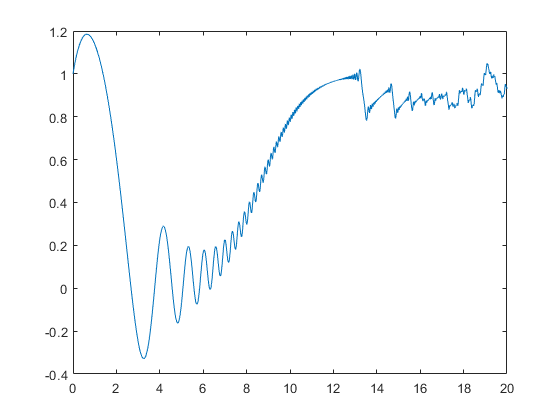

plot(x,y);

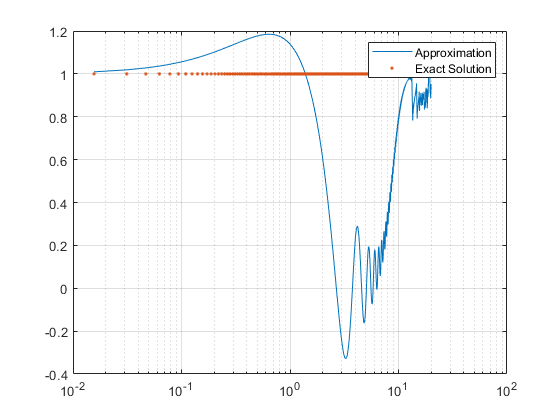

semilogx(x,y,x,q, ".");
legend('Approximation','Exact Solution')
grid on